close('all'); clear; clc;

## Geometry

The Sharp model considers a left-handed frame (North, West, Down).

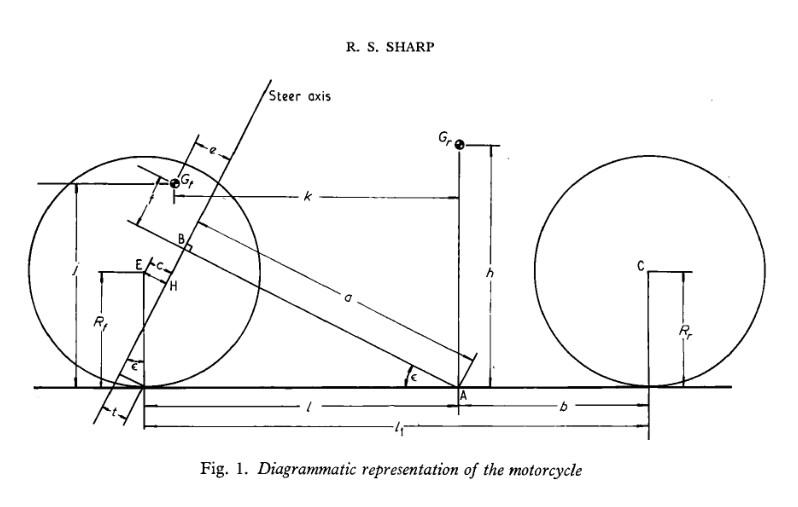

Create the caster frame:

caster = newparams('varepsilon');
N = Frame;
Nc = N.orientNew('y',caster);

Solve for the front wheelbase $l$:

[a,an,l] = newparams('a','a_n','l');
Pa = Point;
Pb = Pa.locateNew(a*Nc.x);
l = solve(cos(caster) == a/(l + an/cos(caster)),l)

$$l = \frac{a-a_{n}}{\cos\left(\varepsilon \right)}$$

Locate the front wheel center $E$:

rf = newparams('r_f');
E = Pa.locateNew(l*N.x - rf*N.z);
rE = E.posFrom

$$rE = \left[\begin{array}{c} \frac{a-a_{n}}{\cos\left(\varepsilon \right)}\\ 0\\ -r_{f} \end{array}\right]$$

Now locate the front wheel center relative to the intersection between the front chassis chord and the steering axis:

rBE = simplify(expand(Ry(caster).'*E.posFrom(Pb)));
lx = rBE(1)

$$lx = r_{f}\,\sin\left(\varepsilon \right)-a_{n}$$

lz = rBE(3)

$$lz = -\frac{r_{f}\,{\cos\left(\varepsilon \right)}^{2}-a\,\sin\left(\varepsilon \right)+a_{n}\,\sin\left(\varepsilon \right)}{\cos\left(\varepsilon \right)}$$

Now solve for the front chassis chord $a$ and the height $f$ of the front chassis mass center in the caster frame to obtain a simplifying substitution for $l_{z}$:

[e,f,j,k] = newparams('e','f','j','k');
Gfa = Pa.locateNew(k*N.x - j*N.z);
Gf = Pb.locateNew(e*Nc.x + f*Nc.z);
sol_af = solve(Gf.posFrom(Gfa) == 0,[a,f]);
lz_sub = simplify(expand(subs(lz,a,sol_af.a)))

$$lz\_sub = -\frac{r_{f}\,{\cos\left(\varepsilon \right)}^{2}+{\cos\left(\varepsilon \right)}^{2}\,\mathrm{i}+a_{n}\,\sin\left(\varepsilon \right)+e\,\sin\left(\varepsilon \right)-k\,\cos\left(\varepsilon \right)\,\sin\left(\varepsilon \right)-\mathrm{i}}{\cos\left(\varepsilon \right)}$$


clearvars -except a an l rf caster lx lz e f j k sol_af;

## Generalized coordinates

Translation of the motorcycle origin $A$:

[x,y] = dynvars('x','y');

Orientation of the rear chassis frame:

[yaw,lean] = dynvars('psi','varphi');

Orientation of the front wheel:

[yaw_f,lean_f] = dynvars('psi_f','varphi_f');

Steering angle:

steer = dynvars('delta');

Rotation angles of the rear and front wheels:

[pitch_r,pitch_f] = dynvars('theta_r','theta_f');

Generalized coordinates:

q = [x,y,yaw,lean,steer,pitch_r,yaw_f,lean_f,pitch_f].';
qd = diff(q);

## Quasi-velocities

u = dynvars('u',1:5);

## Force inputs

Rear and front tire lateral forces:

[Yr,Yf] = dynvars('Y_r','Y_f');

Yrd = diff(Yr);
Yfd = diff(Yf);

Y = [
    Yr;
    Yf
    ];

Yd = [
    Yrd;
    Yfd
    ];

Steering torque:

Msteer = dynvars('tau');

## Kinematics

### Rear chassis

Orientation:

N = Frame;
Nyaw = N.orientNew('z',yaw);
Nlean = Nyaw.orientNew('x',lean);
pprint(Nlean.dcm)

$$\left[\begin{array}{ccc} \cos\left(\psi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\phi \right)\\ \sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & -\cos\left(\psi \right)\,\sin\left(\phi \right)\\ 0 & \sin\left(\phi \right) & \cos\left(\phi \right) \end{array}\right]$$

Position:

P0 = Point;
Pa = P0.locateNew(x.*N.x + y.*N.y);
h = newparams('h');
Gr = Pa.locateNew(-h.*Nlean.z);
pprint(Gr.posFrom)

$$\left[\begin{array}{c} x-h\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y+h\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -h\,\cos\left(\phi \right) \end{array}\right]$$

### Rear wheel

Orientation:

Npitch_r = Nlean.orientNew('y',pitch_r);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta_{r}\right)-\sin\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\theta_{r}\right)+\cos\left(\theta_{r}\right)\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ \cos\left(\theta_{r}\right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & \sin\left(\psi \right)\,\sin\left(\theta_{r}\right)-\cos\left(\psi \right)\,\cos\left(\theta_{r}\right)\,\sin\left(\phi \right)\\ -\cos\left(\phi \right)\,\sin\left(\theta_{r}\right) & \sin\left(\phi \right) & \cos\left(\theta_{r}\right)\,\cos\left(\phi \right) \end{array}\right]$$

Position:

[b,rr] = newparams('b','r_r');
Wr = Pa.locateNew(-b.*Nlean.x -rr.*Nlean.z);
pprint(Wr.posFrom)

$$\left[\begin{array}{c} x-b\,\cos\left(\psi \right)-r_{r}\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y-b\,\sin\left(\psi \right)+r_{r}\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -r_{r}\,\cos\left(\phi \right) \end{array}\right]$$

#### Rear contact point

Cr = Wr.locateNew(rr*Nlean.z);
rWrCr = Cr.posFrom(Wr,Npitch_r);
pprint(rWrCr)

$$\left[\begin{array}{c} -r_{r}\,\sin\left(\theta_{r}\right)\\ 0\\ r_{r}\,\cos\left(\theta_{r}\right) \end{array}\right]$$

### Front chassis

Orientation:

Ncaster = Nlean.orientNew('y',caster);
Nsteer = Ncaster.orientNew('z',steer);

Position:

Pb = Pa.locateNew(a.*Ncaster.x);
Gf = Pb.locateNew(e.*Nsteer.x + f.*Nsteer.z);

### Front wheel

Orientation:

Nyaw_f = N.orientNew('z',yaw_f);
Nlean_f = Nyaw_f.orientNew('x',lean_f);
Npitch_f = Nlean_f.orientNew('y',pitch_f);

Position:

Wf = Pb.locateNew(lx.*Nsteer.x + lz.*Nsteer.z);

#### Front contact point

Cf = Wf.locateNew(rf.*Nlean_f.z);
rWfCf = Cf.posFrom(Wf,Npitch_f);
pprint(rWfCf)

$$\left[\begin{array}{c} -r_{f}\,\sin\left(\theta_{f}\right)\\ 0\\ r_{f}\,\cos\left(\theta_{f}\right) \end{array}\right]$$

## Rigid bodies

### Rear chassis

% mr = newparams('m_r');
% [Irx,Iry,Irz,Crxz] = ...
%     newparams('I_rx','I_ry','I_rz','C_rxz');
% Ir = inertia(Irx,Iry,Irz,'Ixz',Crxz);
% rear_chassis = Body(q,Pose(Nlean,Gr),mr,Ir);

### Rear wheel

% iry = newparams('i_ry');
% Irw = inertia(0,iry,0);
% rear_wheel = Body(q,Pose(Npitch_r,Wr),0,Irw);

### Front chassis

% [mf,Ifx,Ifz] = newparams('m_f','I_fx','I_fz');
% If = inertia(Ifx,0,Ifz);
% front_chassis = Body(q,Pose(Nsteer,Gf),mf,If);

### Front wheel

% ify = newparams('i_fy');
% Ifw = inertia(0,ify,0);
% front_wheel = Body(q,Pose(Npitch_f,Wf),0,Ifw);

## Holonomic constraints

% spin_x = simplify(expand(Nsteer.y(1) - Nlean_f.y(1)));
% spin_z = simplify(expand(Nsteer.y(3) - Nlean_f.y(3)));
% 
% hc = [
%     spin_z;
%     spin_x
%     ];
% 
% pprint(hc)

## Nonholonomic constraints

% no_slip_r = N.x.'*noslip(rear_wheel,rWrCr,Nyaw);
% no_slip_f = N.x.'*noslip(front_wheel,rWfCf,Nyaw_f);
% 
% nhc = [
%     no_slip_r;
%     no_slip_f
%     ];

## Kinematic equations

% kdes = [
%     u(1:2) - Twist(Pose(Nyaw,Pa)).V(4:5);
%     u(3:5) - qd(3:5)
%     ];
% 
% eomk = KinematicEquations(q,u,kdes,"hc",hc,"nhc",nhc);

## Forces and moments

### Rear tire

% Zr = newparams('Z_r');
% rear_wheel.applyForce(Nyaw,Cr,Yr.*N.y + Zr.*N.z);

### Front tire

% Zf = newparams('Z_f');
% front_wheel.applyForce(Nyaw_f,Cf,Yf.*N.y + Zf.*N.z);

### Steering torque

% front_chassis.applyMoment(Nsteer,Msteer.*N.z,rear_chassis);

### Gravity

% bodies = [
%     rear_chassis;
%     rear_wheel;
%     front_chassis;
%     front_wheel
%     ];
% 
% g = newparams('g');
% fg = @(b)b.applyForce(N,Point(b.p),(b.m*g).*N.z);
% arrayfun(fg,bodies);

## Tire equations

% vCr = Twist(Pose(Nyaw,Cr)).V(4:5);
% vCf = Twist(Pose(Nyaw_f,Cf)).V(4:5);
% 
% rl = newparams('sigma');
% [Cr1,Cr2,Cf1,Cf2] = newparams('C_r1','C_r2','C_f1','C_f2');
% 
% eqYr = vCr(1)*(Yr + Cr1*atan(vCr(2)/vCr(1)) - Cr2*lean)./rl;
% eqYf = vCf(1)*(Yf + Cf1*atan(vCf(2)/vCf(1)) - Cf2*lean_f)./rl;
% eqY = [
%     Yrd + eqYr;
%     Yfd + eqYf
%     ];
% 
% eqY = simplify(expand(eqY));

## Joint stiffnesses

% Csteer = newparams('C_delta');
% K = zeros(size(q),'sym');
% K(has(q,steer)) = Csteer;
% pprint(K)

## Dynamical equations